# Maki - Extendend Model 

## Loading data set and defining parameters 

warning('off','all')

% setting working directory
addpath('C:\Users\giwama\Documents\GitHub\Rationality-Enhancement-Toolbox-master\MatlabToolbox')
addpath('C:\Users\giwama\Nextcloud\Proactivity\data');
addpath('C:\Users\giwama\Nextcloud\Proactivity\OSF2\functions');

% importing data
import_data_AXCPT;

% defining meta-control model type
modelName = "InhibitionRecall";
model = @metaControlModelInhibitionRecall;

% Setting experimental cue-probe frequencies
experiment = AXCPTExperiment();
pAX = 0.7; pAY = 0.1; pBX = 0.1; pBY = 0.1; % probability of each trial type
p_cue_probe = [pAX,pAY,pBX,pBY];
experiment.blocks(1).p_trial_type = p_cue_probe;

pA = pAX+pAY/(pAX+pAY+pBX+pBY); % probability of A cue
pB = pBX+pBY/(pAX+pAY+pBX+pBY); % probability of B cue

maxalpha = 10; % to change size of graphs

% arranging data accuracies and conditions
data_AXCPT = table2array(DataAXCPT(:,[2:3,6:13])); 
accuracies = data_AXCPT(:,3:6); % Accuracies for AX, AY, BX and BY trials
RTs = data_AXCPT(:,7:end); % Response Times
reward = data_AXCPT(:,2); % reward condition
cognitive_load = data_AXCPT(:,1); % cognitive load condition
trials = 150; % total number of trials
m = 1; % memory parameter (fixed across all models)
nr_subjects=size(DataAXCPT,1); % sample size
p_slip = 1-mean(accuracies(:,4)); % random error (motor slip) based on error in BY trials
p_random_inhibition = 0.7; % inhibition baseline (only used in models with inhibition)
isNoGo = 0; % Traditional Design = 0, No-Go design = 1


% parameters for predictions
gamma = 1/3; % cost 
load = [1 2 3]; % cognitive load
delta_t = 0.2; % reward of responding faster
lambda = 0.05; % interference of load
control_cost = 0.5; % cognitive control cost (only used in models with inhibition)

## Fitting Meta Control Model Individually

lambda_min = 0; % minimum lambda value

for s=1:nr_subjects
    [pars(s,:), fitted_accs(s,:), ll(s), fitted_p_intentions(s,:), fitted_optimal_cs(s,:), fitted_p_recalls(s,:), bic(s,:)]= ...
        fitMetaControlModel(modelName, isNoGo, accuracies(s,:), cognitive_load(s), trials, m, p_random_inhibition, p_cue_probe, p_slip, lambda_min);
end

## Plot Fitted and Observed Accuracies across Reward Conditions

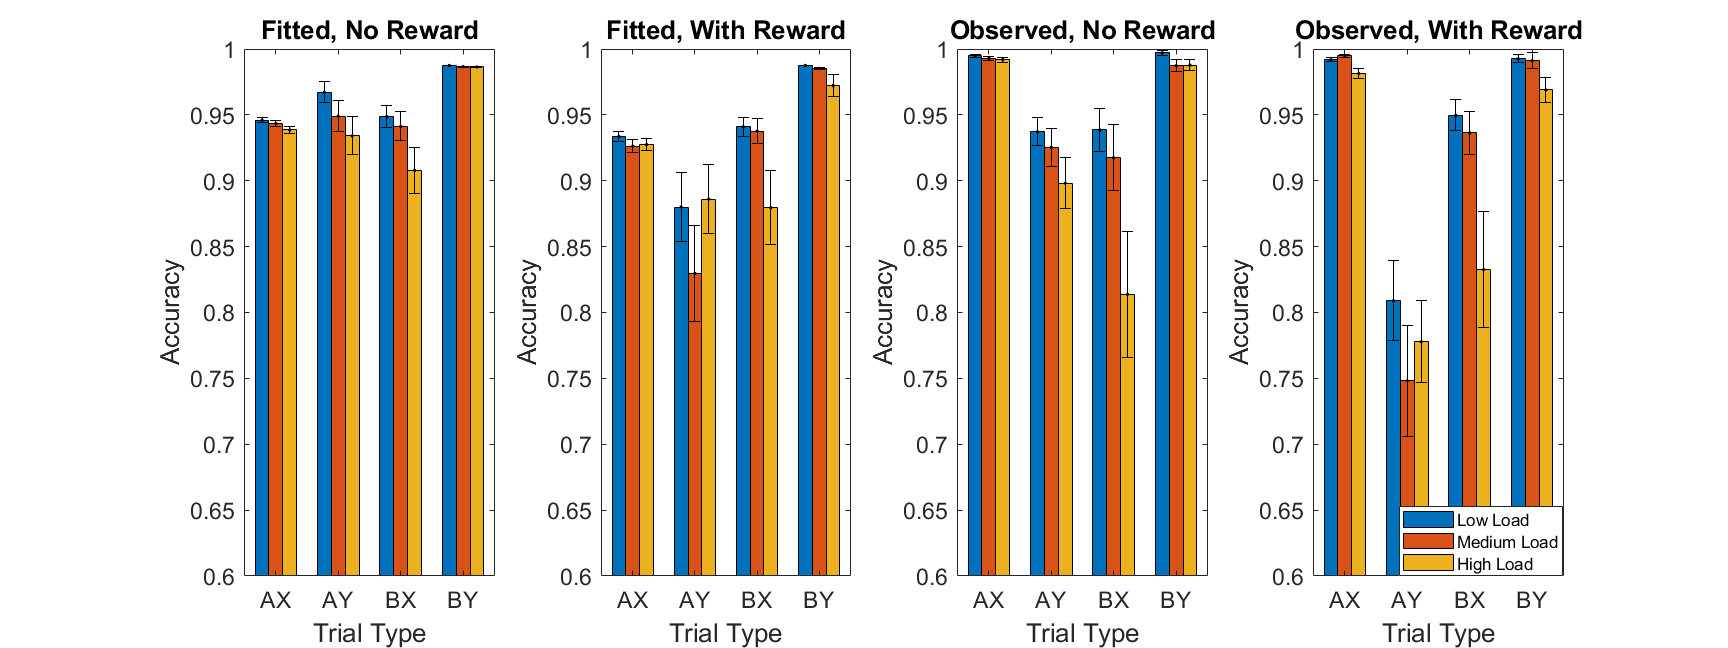

for r=1:2
    for l=1:3
        in_condition = and(cognitive_load==l,reward==(r-1));
        accuracy_people(:,r,l) = mean(fitted_accs(in_condition,:));
        fitted_p_intentions_cond(:,r,l) = mean(fitted_p_intentions(in_condition,:));
        fitted_optimal_cs_cond(:,r,l) =  mean(fitted_optimal_cs(in_condition,:));
        fitted_p_recalls_cond(:,r,l) = mean(fitted_p_recalls(in_condition,:));
        acc_pred_error(:,r,l) = std(fitted_accs(in_condition,:))./sqrt(size(fitted_accs(in_condition,:),1));
        acc_obs_error(:,r,l) = std(accuracies(in_condition,:))./sqrt(size(accuracies(in_condition,:),1));
        fitted_p_intentions_cond_error(:,r,l) = std(fitted_p_intentions(in_condition,:))./sqrt(size(fitted_p_intentions(in_condition,:),1));
        
    end
end

figure('units','normalized','outerposition',[0.1 0.1 0.9 0.6]);
subplot(1,4,1);
y1 = squeeze(accuracy_people(:,1,:));
hBar = bar(y1,1);
err1 = squeeze(acc_pred_error(:,1,:));
xBar=cell2mat(get(hBar,'XData')).' + [hBar.XOffset];  % compute bar centers
hold on;
hEB=errorbar(xBar,y1,err1,'k.');
ylim([0.6,1])
ylabel('Accuracy','FontSize',16);
xlabel('Trial Type');
title('Fitted, No Reward','FontSize',16);
set(gca,'XTickLabel',experiment.trial_types,'FontSize',14);


subplot(1,4,2);
y1 = squeeze(accuracy_people(:,2,:));
hBar = bar(y1,1);
err1 = squeeze(acc_pred_error(:,2,:));
xBar=cell2mat(get(hBar,'XData')).' + [hBar.XOffset];  % compute bar centers
hold on;
hEB=errorbar(xBar,y1,err1,'k.');
ylim([0.6,1]);
ylabel('Accuracy','FontSize',16);
xlabel('Trial Type');
title('Fitted, With Reward','FontSize',16);
set(gca,'XTickLabel',experiment.trial_types,'FontSize',14);


subplot(1,4,3);
y1 = squeeze(accuracies_no_reward');
hBar = bar(y1,1);
err1 = squeeze(acc_obs_error(:,1,:));
xBar=cell2mat(get(hBar,'XData')).' + [hBar.XOffset];  % compute bar centers
hold on
hEB=errorbar(xBar,y1,err1,'k.');
ylim([0.6,1])
ylabel('Accuracy','FontSize',16)
xlabel('Trial Type')
title('Observed, No Reward','FontSize',16)
set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)
%legend('Low Load','Medium Load','High Load')

subplot(1,4,4);
y1 = squeeze(accuracies_with_reward');
hBar = bar(y1,1);
err1 = squeeze(acc_obs_error(:,2,:));
xBar=cell2mat(get(hBar,'XData')).' + [hBar.XOffset];  % compute bar centers
hold on;
hEB=errorbar(xBar,y1,err1,'k.');
ylim([0.6,1]);
ylabel('Accuracy','FontSize',16);
xlabel('Trial Type');
title('Observed, With Reward','FontSize',16);
set(gca,'XTickLabel',experiment.trial_types,'FontSize',14);
legend('Low Load','Medium Load','High Load','FontSize',10,'Position',[0.853 0.16 0.01 0.01]);

## Estimate p(intention), c* and p(recall)

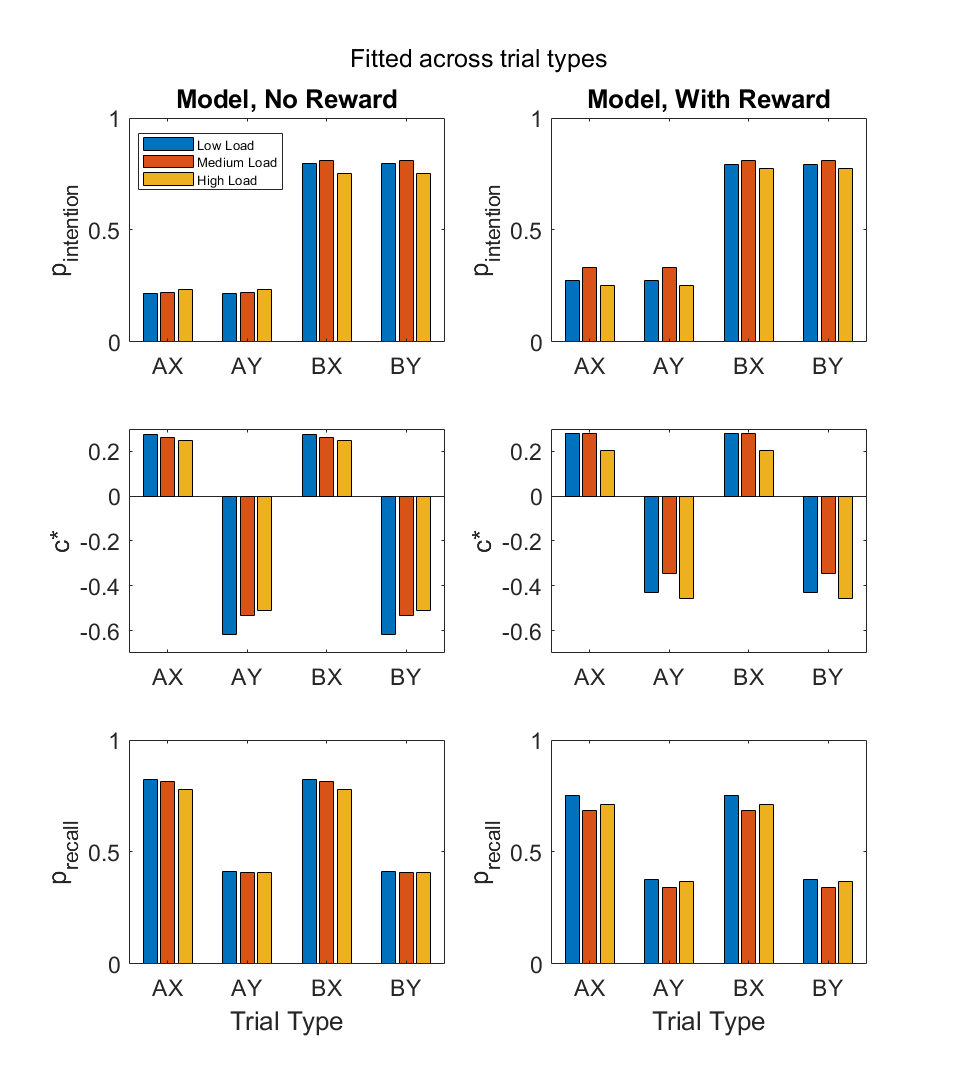

% p(intention)
        figure('units','normalized','outerposition',[0.1 0.005 0.5 1])
        sgtitle({'Fitted across trial types'})
        subplot(3,2,1),
        bar(squeeze(fitted_p_intentions_cond(:,1,:))) % across load conditions - No reward
        ylim([0,1])
        ylabel('p_{intention}','FontSize',16)
        title('Model, No Reward','FontSize',16)
        set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)
        subplot(3,2,2),
        bar(squeeze(fitted_p_intentions_cond(:,2,:))) % across load conditions - with reward
        ylim([0,1])
        ylabel('p_{intention}','FontSize',16)
        title('Model, With Reward','FontSize',16)
        set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)
        
% optimal_c
        subplot(3,2,3),
        bar(squeeze(fitted_optimal_cs_cond(:,1,:))) % across load conditions - No reward
        ylim([-0.7,0.3])
        ylabel('c*','FontSize',16)
        set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)
        subplot(3,2,4),
        bar(squeeze(fitted_optimal_cs_cond(:,2,:))) % across load conditions - with reward
        ylim([-0.7,0.3])
        ylabel('c*','FontSize',16)
        set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)
% p_recall
        subplot(3,2,5),
        bar(squeeze(fitted_p_recalls_cond(:,1,:))) % across load conditions - No reward
        ylim([0,1])
        xlabel('Trial Type')
        ylabel('p_{recall}','FontSize',16)
        set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)
        subplot(3,2,6),
        bar(squeeze(fitted_p_recalls_cond(:,2,:))) % across load conditions - with reward
        ylim([0,1])
        ylabel('p_{recall}','FontSize',16)
        xlabel('Trial Type')
        set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)
        legend('Low Load','Medium Load','High Load','FontSize',8, 'Position', [0.22 0.85 0.000001 0.0001])


% % p_intention for reward conditions (predicted with differences in alpha and deltat_t vs. estimated)
%         figure('units','normalized','outerposition',[0.1 0.1 0.6 0.5])
%         subplot(1,2,1)
%         bar([squeeze(mean(fitted_p_intentions_cond(:,1,:)))'; squeeze(mean(fitted_p_intentions_cond(:,2,:)))']);
%         title('Fitted','FontSize',16)
%         ylabel('P_{intention}')
%         xlabel('Trial Type')
%         ylim([0 0.7])
%         set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',14)
%         legend('Low Load','Medium Load','High Load','FontSize',10, 'Position', [0.17 0.8 0.0000001 0.0001])
% 
% %bar([squeeze(mean(fitted_p_intentions_cond(:,1,:))), squeeze(mean(fitted_p_intentions_cond(:,2,:)))]);

## testing differences across conditions

% alpha
[mean(pars(reward==0,1)), mean(pars(reward==1,1))]

ans =     6.1139    5.5056


[h,p,ci,stats] = ttest2(pars(reward==0,1),pars(reward==1,1))

h = 0

p = 0.2650

ci =    -0.4639
    1.6807


stats = struct with fields:
    tstat: 1.1171
       df: 264
       sd: 4.4405



% alphaAX
[mean(pars(reward==0,2)), mean(pars(reward==1,2))]

ans =     8.8851    8.2932


[h,p,ci,stats] = ttest2(pars(reward==0,2),pars(reward==1,2))

h = 0

p = 0.0975

ci =    -0.1089
    1.2926


stats = struct with fields:
    tstat: 1.6631
       df: 264
       sd: 2.9018



% delta_t
[mean(pars(reward==0,4)), mean(pars(reward==1,4))]

ans =     0.0200    0.3801


[h,p,ci,stats] = ttest2(pars(reward==0,4),pars(reward==1,4))

h = 1

p = 0.0020

ci =    -0.5876
   -0.1325


stats = struct with fields:
    tstat: -3.1154
       df: 264
       sd: 0.9423



% p_intention - A trials
[mean(fitted_p_intentions(reward==0,1)), mean(fitted_p_intentions(reward==1,1))]

ans =     0.2239    0.2875


[std(fitted_p_intentions(reward==0,1)), std(fitted_p_intentions(reward==1,1))]

ans =     0.0691    0.1947


[h,p,ci,stats] = ttest2(fitted_p_intentions(reward==0,1), fitted_p_intentions(reward==1,1))

h = 1

p = 4.9132e-04

ci =    -0.0991
   -0.0281


stats = struct with fields:
    tstat: -3.5293
       df: 264
       sd: 0.1469



% p_intention - B trials
[mean(fitted_p_intentions(reward==0,3)), mean(fitted_p_intentions(reward==1,3))]

ans =     0.7880    0.7930


[std(fitted_p_intentions(reward==0,3)), std(fitted_p_intentions(reward==1,3))]

ans =     0.2290    0.2237


[h,p,ci,stats] = ttest2(fitted_p_intentions(reward==0,3), fitted_p_intentions(reward==1,3))

h = 0

p = 0.8559

ci =    -0.0597
    0.0496


stats = struct with fields:
    tstat: -0.1818
       df: 264
       sd: 0.2263



%p_intention - BX and AY trials
[mean(fitted_p_intentions(:,2)), mean(fitted_p_intentions(:,3))]

ans =     0.2562    0.7906


[std(fitted_p_intentions(:,2)), std(fitted_p_intentions(:,3))]

ans =     0.1501    0.2259


[h,p,ci,stats] = ttest2(fitted_p_intentions(:,2), fitted_p_intentions(:,3))

h = 1

p = 1.5732e-126

ci =    -0.5670
   -0.5017


stats = struct with fields:
    tstat: -32.1332
       df: 530
       sd: 0.1918


## Measuring Proactivity (on fitted_accs)

p_AS;

for s=1:nr_subjects 
   
   for tt=1:4
        prob = p_cue_probe(tt);
        inds = [tt,tt+4];
        acc = max(0.0001,min(0.9999,fitted_accs(s,tt)));
        probs = [acc,1-acc];
        GD_by_participant_and_tt(s,tt)=MeasureGoalDirectedness(...
            probs,1/prob*p_AS_no_goal(inds),1:2);
 
    end
     accuracy_by_participant(s) = dot(fitted_accs(s,:),experiment.blocks(1).p_trial_type);
     accs = max(0.00001,min(0.99999,fitted_accs(s,:)));    
     p_SA2 = [p_cue_probe.*accs,experiment.blocks(1).p_trial_type.*(1-accs)];
     GD_fitted(s,1) = MeasureGoalDirectedness(p_SA2,p_AS_no_goal,1:8);
     reactivity_fitted(s,1) = MeasureReactivity(p_SA2,p_AS_no_stimulus_reactive,1:8); 
 
end

[h,p,ci,stats]= ttest2(GD_fitted(reward==0),GD_fitted(reward==1))

h = 1

p = 0.0043

ci =    -0.0442
   -0.0083


stats = struct with fields:
    tstat: -2.8826
       df: 264
       sd: 0.0743




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## META CONTROL PREDICTIONS AX-CPT 70-10-10-10 %%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Mean fitted parameters to use in the predictions

mean_alpha = [mean(pars(:,1)), mean(pars(reward==0,1)), mean(pars(reward==1,1))];
mean_control_cost = [mean(pars(:,2)), mean(pars(reward==0,2)), mean(pars(reward==1,2))];
mean_delta_t = [mean(pars(:,3)), mean(pars(reward==0,3)), mean(pars(reward==1,3))];
mean_interference = [mean(pars(:,4)), mean(pars(reward==0,4)), mean(pars(reward==1,4))];

## Step 1: proactive intention setting - CUE

% Probability of correct response according to each strategy and cognitive load
p_correct_reactive=[pAX/(pAX+pBX), 1, 1-pAX/(pAX+pBX), 1]*(1-p_slip) + ...
                     [1-pAX/(pAX+pBX), 0, pAX/(pAX+pBX), 0]*(p_slip); % according to Hernstein's matching law

for l=1:numel(load)
    p_correct_proactive(l,:) = [pAX/pA - 0.05*(load(l)-1), ...
                               1-pAX/(pAX+pAY) + 0.05*(load(l)-1), ...
                               (pBX+pBY)/pB - 0.05*(load(l)-1), ...
                               (pBX+pBY)/pB - 0.05*(load(l)-1)]*(1-p_slip) + ...
                               p_slip*[(1-pAX/pA) + 0.05*(load(l)-1), ...
                               (1-pAY/pA) - 0.05*(load(l)-1), ...
                               1-((pBX+pBY)/pB) + 0.05*(load(l)-1), ...
                               1-((pBX+pBY)/pB) + 0.05*(load(l)-1)];
end

## benefit of setting an intention instead of reactive

        delta_acc = p_correct_proactive-p_correct_reactive

delta_acc =          0   -0.8532    0.8532         0
   -0.0488   -0.8044    0.8044   -0.0488
   -0.0975   -0.7557    0.7557   -0.0975



% Probability of each trial type given a specific cue or probe
        p_given_A=[pAX/(pAX+pAY), pAY/(pAX+pAY), 0, 0]; % probability of trial type given A
        p_given_B=[0, 0, pBX/(pBX+pBY), pBY/(pBX+pBY)]; % probability of trial type given B
        p_given_X=[pAX/(pAX+pBX), 0, pBX/(pAX+pBX), 0]; % probability of trial type given X
        p_given_Y=[0, pAY/(pAY+pBY), 0, pBY/(pAY+pBY)]; % probability of trial type given Y

% benefit of using proactive control for each trial type
for l=1:numel(load)
        E_delta_acc_A(l,:) = dot(delta_acc(l,:),p_given_A);
        E_delta_acc_B(l,:) = dot(delta_acc(l,:),p_given_B);
        E_delta_acc_X(l,:) = dot(delta_acc(l,:),p_given_X);
        E_delta_acc_Y(l,:) = dot(delta_acc(l,:),p_given_Y);
end

% Overall benefit of proactive control over habitual for each cue considering cost
        net_benefit_A = @(ratio,l) E_delta_acc_A(l,:)*ratio+delta_t-gamma; 
        net_benefit_B = @(ratio,l) E_delta_acc_B(l,:)*ratio+delta_t-gamma;

        %net_benefit_A = @(ratio,l) E_delta_acc_A(l,:)*ratio+ratio/5-gamma; 
        %net_benefit_B = @(ratio,l) E_delta_acc_B(l,:)*ratio+ratio/5-gamma;

## Cost-Benefit analysis of set intention for each cue

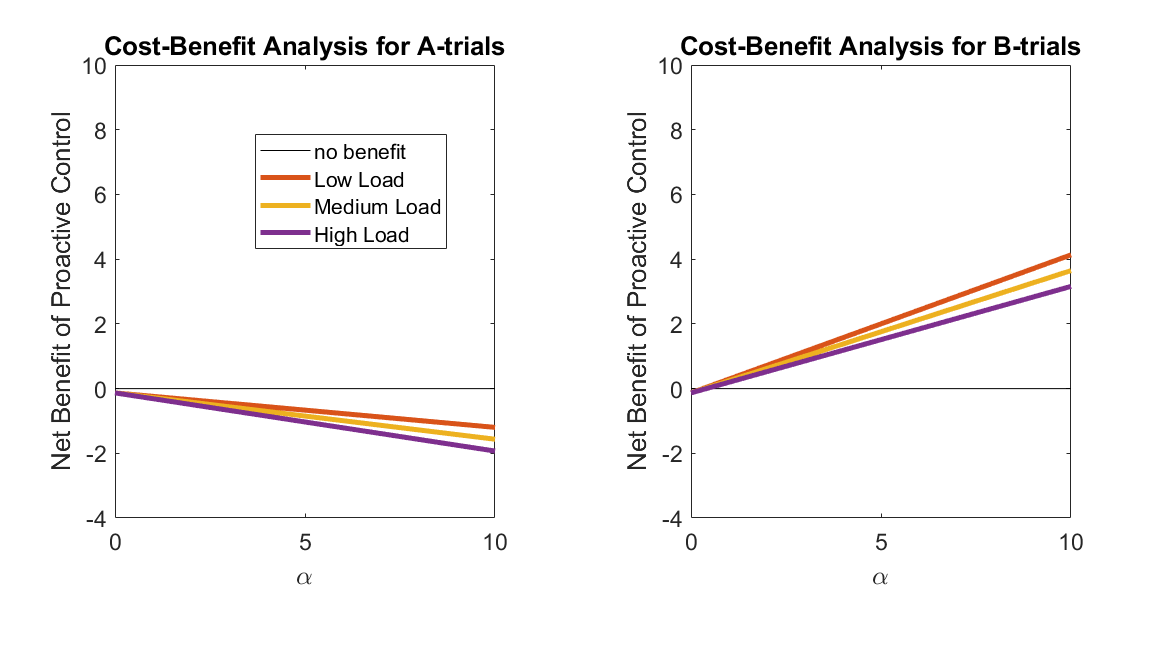

        choose_proactivity_A = @(ratio,l) net_benefit_A(ratio,l)>0;
        choose_proactivity_B = @(ratio,l) net_benefit_B(ratio,l)>0;

% Plot benefit for each cue for different Alphas
        ratios = linspace(0,maxalpha,101);

        figure('units','normalized','outerposition',[0.2 0.2 0.6 0.6])
        subplot(1,2,1)
        plot(ratios,zeros(1,101),'k-'),hold on
        xlabel('\alpha','FontSize',16)
        ylabel('Net Benefit of Proactive Control','FontSize',16)
        set(gca,'FontSize',14,'Position',[0.1 .2 0.33 0.70])
        xlim([0,maxalpha]),ylim([-4,10])
        for l=1:numel(load) 
            plot(ratios,net_benefit_A(ratios,l),'LineWidth',3), hold on
        end
        %legend({'no benefit','Low Load', 'Medium Load','High Load'})
        title('Cost-Benefit Analysis for A-trials')

        subplot(1,2,2)
        plot(ratios,zeros(1,101),'k-'),hold on
        xlabel('\alpha','FontSize',16)
        ylabel('Net Benefit of Proactive Control','FontSize',16)
        xlim([0,maxalpha]),ylim([-4,10])
        set(gca,'FontSize',14, 'Position',[0.6 .2 0.33 0.7])
        for n=1:numel(load) 
            plot(ratios,net_benefit_B(ratios,n),'LineWidth',3), hold on
        end
        legend({'no benefit','Low Load', 'Medium Load','High Load'}, 'Position',[0.3 0.7 0.01 0.01])
        title('Cost-Benefit Analysis for B-trials')

## Transform net benefit to fit between 0 an 1 (Probability)

        p_proactive_A = @(ratio,n) sigmoid(net_benefit_A(ratio,n))

p_proactive_A = function_handle with value:
    @(ratio,n)sigmoid(net_benefit_A(ratio,n))


        p_proactive_B = @(ratio,n) sigmoid(net_benefit_B(ratio,n))

p_proactive_B = function_handle with value:
    @(ratio,n)sigmoid(net_benefit_B(ratio,n))


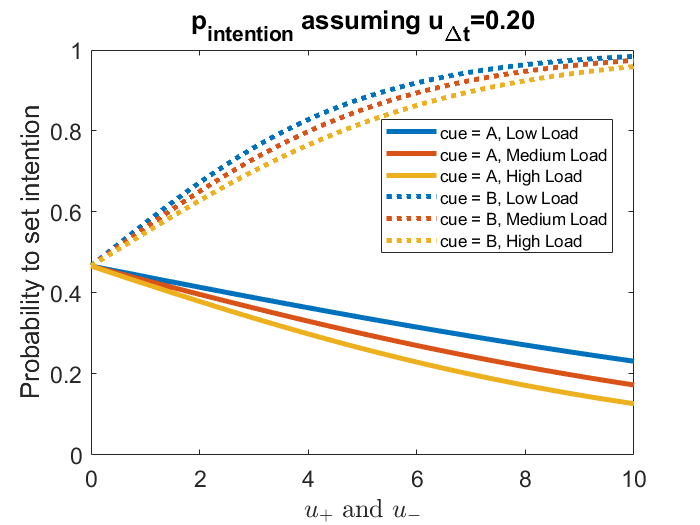


% Probability to set a proactive intention for each cue 
        figure()
        for l=1:numel(load)
            plot(ratios,p_proactive_A(ratios,l),'-','LineWidth',3),hold on 
        end
        plot(ratios,p_proactive_B(ratios,1),':','color',[0, 0.4470, 0.7410],'LineWidth',3)
        plot(ratios,p_proactive_B(ratios,2),':','color',[0.8500, 0.3250, 0.0980],'LineWidth',3)
        plot(ratios,p_proactive_B(ratios,3),':','color',[0.9290, 0.6940, 0.1250],'LineWidth',3)
        xlabel('$u_+$ and $u_-$','interpreter','latex','FontSize',16)
        ylabel('Probability to set intention','FontSize',16)
        title(['p_{intention} assuming u_{\Delta{}t}=', num2str(delta_t,'%.2f')])
        xlim([0,maxalpha])
        set(gca,'FontSize',14)
        legend({'cue = A, Low Load','cue = A, Medium Load', 'cue = A, High Load','cue = B, Low Load','cue = B, Medium Load', 'cue = B, High Load'},'FontSize',10,'Position',[0.705 0.64 0.01 0.01])

## Step 2: Deciding whether to boost or inhibit the execution of a proactively set intention

control signal that shifts the probability that the decision will be determined by the proactively formed intention away from 50%

        control_intensities=linspace(-0.7,0.3,301);

% expected benefit of exerting the control signal 
%assumptions: alpha=delta_t,  (delta_t+E_delta_acc_X*alpha)*c
        benefit_c_X = @(c,alpha,delta_t,l) (E_delta_acc_X(l,:)*alpha+delta_t)*c %7/8*alpha*c+1/8*(2*alpha*c);

benefit_c_X = function_handle with value:
    @(c,alpha,delta_t,l)(E_delta_acc_X(l,:)*alpha+delta_t)*c


        benefit_c_Y = @(c,alpha,delta_t,l) (E_delta_acc_Y(l,:)*alpha+delta_t)*c%1/2*alpha*c-1/2*2*alpha*c;

benefit_c_Y = function_handle with value:
    @(c,alpha,delta_t,l)(E_delta_acc_Y(l,:)*alpha+delta_t)*c


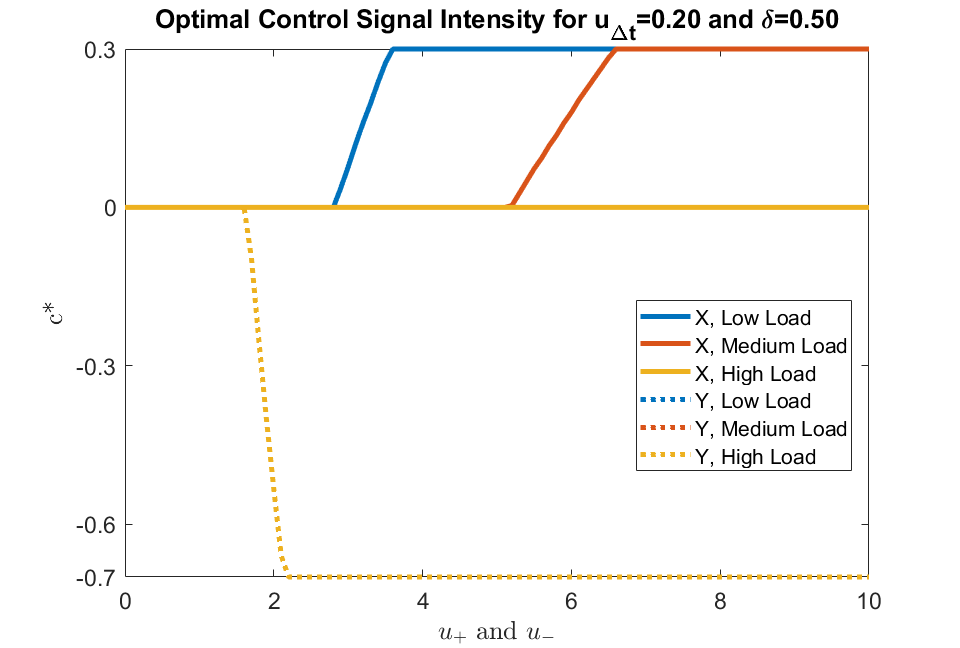

        cost = @(c) exp(control_cost*abs(c));%-1;

        alphas=linspace(0,maxalpha,101);
        delta_ts=delta_t;%alphas/5;

% optimal control signal intensities for different alphas
        for i=1:numel(alphas)
            for l=1:numel(load)
                pos=argmax( benefit_c_X(control_intensities,alphas(i),delta_ts,l) -cost(control_intensities) );
                optimal_c_X(l,i)=control_intensities(pos);

                pos=argmax( benefit_c_Y(control_intensities,alphas(i),delta_ts,l) -cost(control_intensities) );
                optimal_c_Y(l,i)=control_intensities(pos);
            end
        end

% Plot Optimal Control Signal for different alphas
        figure('units','normalized','outerposition',[0.2 0.2 0.5 0.6])
        plot(alphas,optimal_c_X,'LineWidth',3),hold on
        plot(alphas,optimal_c_Y(1,:),':','color',[0, 0.4470, 0.7410],'LineWidth',3)
        plot(alphas,optimal_c_Y(2,:),':','color',[0.8500, 0.3250, 0.0980],'LineWidth',3)
        plot(alphas,optimal_c_Y(3,:),':','color',[0.9290, 0.6940, 0.1250],'LineWidth',3)
        set(gca,'FontSize',14)
        xlabel('$u_+$ and $u_-$','interpreter','latex','FontSize',16)
        ylim([-0.7 0.3])
        yticks([-0.7 -0.6 -0.3 0 0.3])
        title(['Optimal Control Signal Intensity for u_{\Delta{}t}=',num2str(delta_ts, '%.2f'),' and {\delta}=', num2str(control_cost,'%.2f')],'FontSize',14) %'interpreter','latex','FontSize',16)
        ylabel('c*','interpreter','latex','FontSize',16)
        legend({'X, Low Load','X, Medium Load','X, High Load', 'Y, Low Load','Y, Medium Load', 'Y, High Load'}, 'Position',[0.77 0.4 0.01 0.01])

## Decision 3: Deciding wether to recall the rules and cue in the absence of a proactive intention or if intention was inhibited

        for l = 1:numel(load)
            p_correct_recall(l,:) = [m-0.05*(load(l)-1), m-0.05*(load(l)-1), m-0.05*(load(l)-1), m-0.05*(load(l)-1)]*(1-p_slip)...
            + p_slip*[1-(m-0.05*(load(l)-1)), 1-(m-0.05*(load(l)-1)), 1-(m-0.05*(load(l)-1)), 1-(m-0.05*(load(l)-1))];
        end

        delta_acc_recall = p_correct_recall-p_correct_reactive;

% benefit of using recalling the rules for each trial type
        for l = 1:numel(load)
            E_delta_acc_recall_A(l) = dot(delta_acc_recall(l,:),p_given_A);
            E_delta_acc_recall_B(l) = dot(delta_acc_recall(l,:),p_given_B);
            E_delta_acc_recall_X(l) = dot(delta_acc_recall(l,:),p_given_X);
            E_delta_acc_recall_Y(l) = dot(delta_acc_recall(l,:),p_given_Y);
        end

% Overall benefit of recalling the rules over habitual for each cue considering cost
        net_benefit_recall_X = @(ratio,l) E_delta_acc_recall_X(l)*ratio-delta_t-gamma;%ratio/5-gamma%(ratio/4)-gamma;
        net_benefit_recall_Y = @(ratio,l) E_delta_acc_recall_Y(l)*ratio-delta_t-gamma;%ratio/5-gamma%(ratio/4)-gamma;


% Cost-Benefit analysis of recalling the rules for each cue
% choose_proactivity_A = @(ratio,l) net_benefit_A(ratio,l)>0;
% choose_proactivity_B = @(ratio,l) net_benefit_B(ratio,l)>0;

% Plot benefit for each cue for different alphas
        ratios = linspace(0,maxalpha,101);
% 
% figure('units','normalized','outerposition',[0.2 0.2 0.67 0.6])
% subplot(1,2,1)
% plot(ratios,zeros(1,101),'k-'),hold on
% xlabel('$u_+$ and $u_-$','interpreter','latex','FontSize',16)
% ylabel('Net Benefit of p_{recall}','FontSize',16)
% set(gca,'FontSize',14)
% xlim([0,maxalpha]),ylim([-3,4])
% for l=1:numel(load) 
%     plot(ratios,net_benefit_recall_X(ratios,l),'LineWidth',3), hold on
% end
% %legend({'no benefit','Low Load', 'Medium Load','High Load'})
% title('Cost-Benefit Analysis of p_{recall} for X-probes')
% 
% subplot(1,2,2)
% plot(ratios,zeros(1,101),'k-'),hold on
% xlabel('Reward parameter \alpha','FontSize',16)
% ylabel('Net Benefit of p_{recall}','FontSize',16)
% xlim([0,maxalpha]),ylim([-3,4])
% set(gca,'FontSize',14)
% for l=1:numel(load) 
%     plot(ratios,net_benefit_recall_Y(ratios, l),'LineWidth',3), hold on
% end
% legend({'no benefit','Low Load', 'Medium Load','High Load'},'Position',[0.82 0.5 0.01 0.01])
% title('Cost-Benefit Analysis of p_{recall} for Y-probes')
% 
% 
% % Transform net benefit of recalling to fit between 0 an 1 (Probability)
        p_recall_X = @(ratio,l) sigmoid(net_benefit_recall_X(ratio,l))

p_recall_X = function_handle with value:
    @(ratio,l)sigmoid(net_benefit_recall_X(ratio,l))


        p_recall_Y = @(ratio,l) sigmoid(net_benefit_recall_Y(ratio,l))

p_recall_Y = function_handle with value:
    @(ratio,l)sigmoid(net_benefit_recall_Y(ratio,l))


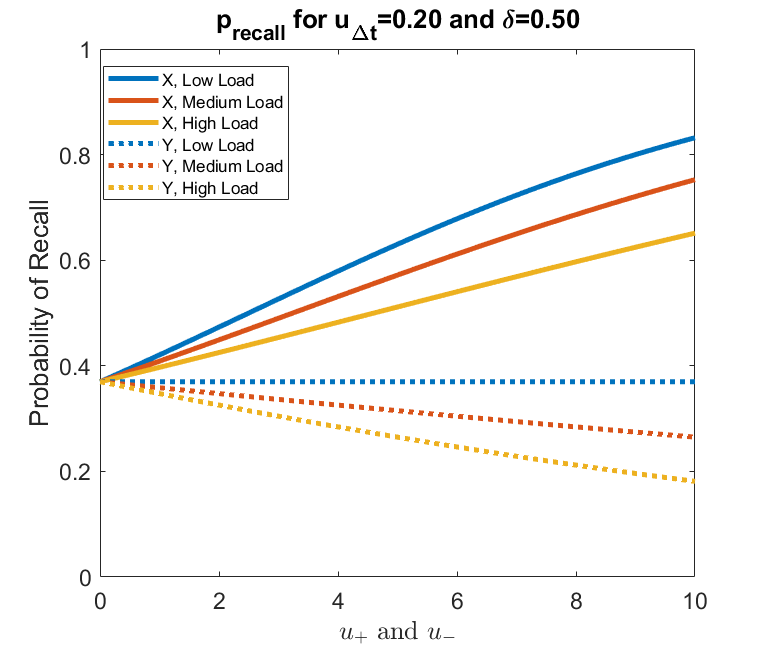

% 
% % Plot Probability to recall for each probe for each probe 
% figure('units','normalized','outerposition',[0.2 0.2 0.5 0.6])
% subplot(1,2,1)
% for l=1:numel(load)
%     plot(ratios,p_recall_X(ratios,l),'LineWidth',3),hold on 
% end
% title('p(recall) for X trials','FontSize',16)
% xlabel('Reward parameter alpha','FontSize',16)
% ylabel('Probability of Recall','FontSize',16)
% xlim([0,maxalpha])
% ylim([0,1])
% set(gca,'FontSize',14)
% %legend({'Low Load', 'Medium Load','High Load'})
% 
% subplot(1,2,2)
% for l=1:numel(load)
%     plot(ratios,p_recall_Y(ratios,l),'LineWidth',3),hold on
% end
% title('p(recall)for Y trials','FontSize',16)
% xlabel('$u_+$ and $u_-$','interpreter','latex','FontSize',16)
% ylabel('Probability of Recall','FontSize',16)
% xlim([0,maxalpha])
% ylim([0,1])
% set(gca,'FontSize',14)
% legend({'Low Load', 'Medium Load','High Load'})

% Probability to recall for each probe
        figure('units','normalized','outerposition',[0.2 0.2 0.4 0.6])
        for l=1:numel(load)
            plot(ratios,p_recall_X(ratios,l),'-','LineWidth',3),hold on 
        end
        plot(ratios,p_recall_Y(ratios,1),':','color',[0, 0.4470, 0.7410],'LineWidth',3)
        plot(ratios,p_recall_Y(ratios,2),':','color',[0.8500, 0.3250, 0.0980],'LineWidth',3)
        plot(ratios,p_recall_Y(ratios,3),':','color',[0.9290, 0.6940, 0.1250],'LineWidth',3)
        xlabel('$u_+$ and $u_-$','interpreter','latex','FontSize',16)
        ylabel('Probability of Recall','FontSize',16)
        xlim([0,maxalpha])
        ylim([0,1])
        set(gca,'FontSize',14)
        title(['p_{recall} for u_{\Delta{}t}=',num2str(delta_t, '%.2f'),' and {\delta}=', num2str(control_cost, '%.2f')]) %'interpreter','latex','FontSize',16)
        legend({'X, Low Load','X, Medium Load','X, High Load', 'Y, Low Load','Y, Medium Load', 'Y, High Load'},'FontSize',10,'Position',[0.25 0.79 0.01 0.01])

## Model predictions for different reward and delta_t

fitting the model for no reward condition individual fit - alphaAX e deltat +1

clear acc_pred pred_w_reactive pred_w_proactive pred_p_intentions pred_optimal_cs pred_p_recalls;

        alphas_p = [pars(reward==0,1)'].*1;
        alphasAX_p = [pars(reward==0,2)'] + 1; 
        delta_ts_p = [pars(reward==0,4)'] + 1 ; 
        control_cost_p = [pars(reward==0,3)']; 
        interference_p = [pars(reward==0,5)'];
        load_p = cognitive_load(reward==0);
   
for s=1:size(accuracies(reward==0,1))
        [acc_pred(s,:), pred_p_intentions(s,:), pred_optimal_cs(s,:), pred_p_recalls(s,:)] = ...
         model(alphas_p(s),alphasAX_p(s),gamma,load_p(s),control_cost_p(s),delta_ts_p(s),interference_p(s),m,p_random_inhibition,p_cue_probe,p_slip);
end

## Measuring Goal Directedness and Reactivity (predicted)

for s=1:size(accuracies(reward==0,1))
   for tt=1:4
       prob = p_cue_probe(tt);
       inds = [tt,tt+4];
       acc = max(0.0001,min(0.9999,acc_pred(s,tt)));
       probs = [acc,1-acc];
       GD_by_participant_and_tt(s,tt)=MeasureGoalDirectedness(...
           probs,1/prob*p_AS_no_goal(inds),1:2);
 
    end
    accuracy_by_participant(s) = dot(accuracies(s,:),experiment.blocks(1).p_trial_type);
    accs = max(0.00001,min(0.99999,acc_pred(s,:)));    
    p_SA3 = [p_cue_probe.*accs,...
       experiment.blocks(1).p_trial_type.*(1-accs)];
    GD_pred(s,1) = MeasureGoalDirectedness(...
           p_SA3,p_AS_no_goal,1:8);
    reactivity_pred(s,1) = MeasureReactivity(...
           p_SA3,p_AS_no_stimulus_reactive,1:8); 

end

% Meand and SD of proactivity with (predicted) and without reward (fitted)
[mean(GD_fitted(reward==0)), mean(GD_pred)]

ans =     0.2996    0.3351


[std(GD_fitted(reward==0)), std(GD_pred)]

ans =     0.0429    0.0493



[h,p,ci,stats] = ttest2(GD_fitted(reward==0), GD_pred)

h = 1

p = 1.9367e-09

ci =    -0.0468
   -0.0243


stats = struct with fields:
    tstat: -6.2235
       df: 260
       sd: 0.0462


## plot predictions for alphaAX + 1 and delta_t + 1

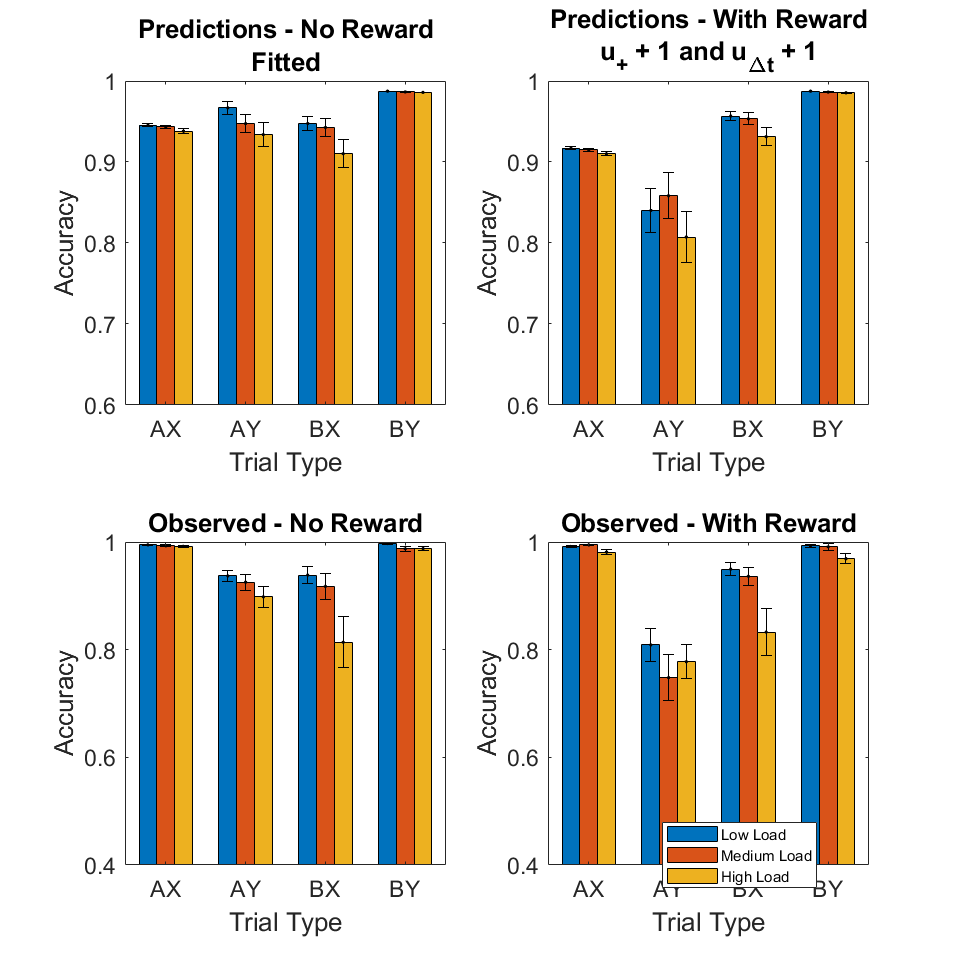

for r=1:2
    for l=1:3
        in_condition = and(cognitive_load==l,reward==(r-1));
        accuracy_people(:,r,l) = mean(fitted_accs(in_condition,:));
        fitted_p_intentions_cond(:,r,l) = mean(fitted_p_intentions(in_condition,:));
        fitted_optimal_cs_cond(:,r,l) =  mean(fitted_optimal_cs(in_condition,:));
        fitted_p_recalls_cond(:,r,l) = mean(fitted_p_recalls(in_condition,:));
        acc_pred_error_no_reward(:,r,l) = std(fitted_accs(in_condition,:))./sqrt(size(fitted_accs(in_condition,:),1)); 
        acc_obs_error(:,r,l) = std(accuracies(in_condition,:))./sqrt(size(accuracies(in_condition,:),1));
        fitted_p_intentions_cond_error(:,r,l) = std(fitted_p_intentions(in_condition,:))./sqrt(size(fitted_p_intentions(in_condition,:),1));
        GD_fitted_cond(:,r,l) = mean(GD_fitted(in_condition,:));
        GD_fitted_cond_error(:,r,l) = std(GD_fitted(in_condition,:))./sqrt(size(GD_fitted(in_condition,:),1));
    end
end

for l=1:3
    acc_ind_reward(:,l) = mean(acc_pred(load_p==l, :)); 
    pred_acc_error_reward(:,l) = std(acc_pred(load_p==l,:))./sqrt(size(acc_pred(load_p==l,:),1));
    pred_p_intentions2(:,l) = mean(pred_p_intentions(load_p==l,:));
    pred_optimal_cs2(:,l) = mean(pred_optimal_cs(load_p==l,:));
    pred_p_recalls2(:,l) = mean(pred_p_recalls(load_p==l,:));
    pred_p_intentions2_error(:,l) = std(pred_p_intentions(load_p==l,:))./sqrt(size(pred_p_intentions(load_p==l,:),1));
    GD_pred2(:,l) = mean(GD_pred(load_p==l,:))';
    GD_pred2_error(:,l) = std(GD_pred(load_p==l,:))./sqrt(size(GD_pred(load_p==l,:),1))';
end


% figure('units','normalized','outerposition',[0.1 0.1 0.5 0.9])
% subplot(1,2,1),
% %bar([squeeze(accuracy_people(:,1,:))]) % across cognitive load conditions - no reward
% y1 = squeeze(accuracy_people(:,1,:));
% hBar = bar(y1,1);
% err1 = squeeze(acc_pred_error_no_reward(:,1,:));
% xBar=cell2mat(get(hBar,'XData')).' + [hBar.XOffset];  % compute bar centers
% hold on
% hEB=errorbar(xBar,y1,err1,'k.');
% ylim([0.6,1])
% yticks([.6 .7 .8 .9 1])
% ylabel('Accuracy','FontSize',16)
% xlabel('Trial Type','FontSize',16)
% title({'Predictions - No Reward','Fitted'})
% %title({'Model Predictions - No Reward',['\alpha=', num2str(alphas(1), '%.2f'),'; u_{\Delta{}t}=', num2str(delta_ts(1),'%.2f'),';'], ['\lambda=', num2str(interference(1), '%.2f'), '; \delta=', num2str(control_cost(1),'%.2f')]},'FontSize',16)
% %legend('Low Load','Medium Load','High Load','FontSize',10)
% set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)
% 
% subplot(1,2,2),
% %bar([acc_ind_reward]) % across cognitive load conditions - with reward
% y1 = [acc_ind_reward];
% hBar = bar(y1,1);
% err1 = squeeze(pred_acc_error_reward);
% xBar=cell2mat(get(hBar,'XData')).' + [hBar.XOffset];  % compute bar centers
% hold on
% hEB=errorbar(xBar,y1,err1,'k.');
% ylim([0.6,1])
% yticks([.6 .7 .8 .9 1])
% ylabel('Accuracy','FontSize',16)
% xlabel('Trial Type','FontSize',16)
% title({'Predictions - With Reward','u_+ + 1 and u_{\Delta{}t} + 1'})
% %title({'Model Predictions - With Reward', ['\alpha=', num2str(alphas(2), '%.2f'),'; u_{\Delta{}t}=', num2str(delta_ts(2),'%.2f'),';'], ['\lambda=', num2str(interference(2), '%.2f'), '; \delta=', num2str(control_cost(2),'%.2f')]},'FontSize',16)
% %legend('Low Load','Medium Load','High Load','FontSize',10)
% set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)

% Predicted and Observed accuracies
        figure('units','normalized','outerposition',[0.1 0.1 0.5 0.9])
        subplot(2,2,1),
        %bar([squeeze(accuracy_people(:,1,:))]) % across cognitive load conditions - no reward
        y1 = squeeze(accuracy_people(:,1,:));
        hBar = bar(y1,1);
        err1 = squeeze(acc_pred_error_no_reward(:,1,:));
        xBar=cell2mat(get(hBar,'XData')).' + [hBar.XOffset];  % compute bar centers
        hold on
        hEB=errorbar(xBar,y1,err1,'k.');
        ylim([0.6,1])
        ylabel('Accuracy','FontSize',16)
        xlabel('Trial Type','FontSize',16)
        title({'Predictions - No Reward','Fitted'})
        %title({'Model Predictions - No Reward',['\alpha=', num2str(alphas(1), '%.2f'),'; u_{\Delta{}t}=', num2str(delta_ts(1),'%.2f'),';'], ['\lambda=', num2str(interference(1), '%.2f'), '; \delta=', num2str(control_cost(1),'%.2f')]},'FontSize',16)
        %legend('Low Load','Medium Load','High Load','FontSize',10)
        set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)

        subplot(2,2,2),
        %bar([acc_ind_reward]) % across cognitive load conditions - with reward
        y1 = [acc_ind_reward];
        hBar = bar(y1,1);
        err1 = squeeze(pred_acc_error_reward);
        xBar=cell2mat(get(hBar,'XData')).' + [hBar.XOffset];  % compute bar centers
        hold on
        hEB=errorbar(xBar,y1,err1,'k.');
        ylim([0.6,1])
        ylabel('Accuracy','FontSize',16)
        xlabel('Trial Type','FontSize',16)
        title({'Predictions - With Reward','u_+ + 1 and u_{\Delta{}t} + 1'})
        %title({'Model Predictions - With Reward', ['\alpha=', num2str(alphas(2), '%.2f'),'; u_{\Delta{}t}=', num2str(delta_ts(2),'%.2f'),';'], ['\lambda=', num2str(interference(2), '%.2f'), '; \delta=', num2str(control_cost(2),'%.2f')]},'FontSize',16)
        %legend('Low Load','Medium Load','High Load','FontSize',10)
        set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)

        subplot(2,2,3),
        y1 = [accuracies_no_reward'];
        hBar = bar(y1,1);
        err1 = squeeze(acc_obs_error(:,1,:));
        xBar=cell2mat(get(hBar,'XData')).' + [hBar.XOffset]; 
        hold on
        hEB=errorbar(xBar,y1,err1,'k.'); % across cognitive load conditions - no reward
        %bar([squeeze(predicted_accuracy(:,1,1)), accuracies_cond(1,:)'])
        ylim([0.4,1])
        ylabel('Accuracy','FontSize',16)
        xlabel('Trial Type','FontSize',16)
        title('Observed - No Reward','FontSize',16)
        %legend('Low Load','Medium Load','High Load','FontSize',10)
        set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)

        subplot(2,2,4),
        y1 = [accuracies_with_reward'];
        hBar = bar(y1,1);
        err1 = squeeze(acc_obs_error(:,2,:));
        xBar=cell2mat(get(hBar,'XData')).' + [hBar.XOffset];  % compute bar centers
        hold on
        hEB=errorbar(xBar,y1,err1,'k.'); % across cognitive load conditions - with reward
        ylim([0.4,1])
        ylabel('Accuracy','FontSize',16)
        xlabel('Trial Type','FontSize',16)
        title('Observed - With Reward','FontSize',16)
        legend('Low Load','Medium Load','High Load','FontSize',9, 'Position', [0.77 0.115 0.001 0.01])
        set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)
        
subplot(2,2,1)
xlim([0.49 4.51])
ylim([0.600 1.000])
subplot(2,2,2)
xlim([0.49 4.51])
ylim([0.600 1.000])
subplot(2,2,3)
xlim([0.49 4.51])
ylim([0.400 1.000])
subplot(2,2,4)
ylim([0.400 1.000])

## p intention for A trials - error bar

        M1 = mean(fitted_p_intentions(reward==0,1));
        M2 = mean(pred_p_intentions(:,1));
        M3 = mean(fitted_p_intentions(reward==1,1));
        SEM1 = std(fitted_p_intentions(reward==0,1))./sqrt(size(fitted_p_intentions(reward==0,1),1));
        SEM2 = std(pred_p_intentions(:,1))./sqrt(size(pred_p_intentions(:,1),1));
        SEM3 = std(fitted_p_intentions(reward==1,1))./sqrt(size(fitted_p_intentions(reward==1,1),1));

% p(intention) A trials
        figure('units','normalized','outerposition',[0.1 0.005 0.5 0.6])
        subplot(1,2,1),
        y1 = [M1,M2];
        x1 = [1 2]

x1 =      1     2


        hBar = bar(x1,y1);
        err1 = [SEM1,SEM2];
        hold on
        hEB=errorbar(x1,y1,err1,'k.');
        ylim([0,.5])
        yticks([0 .1 .2 .3 .4 .5])
        ylabel('p_{intention}','FontSize',16)
        title({'Predicted','A trials'},'FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)
        subplot(1,2,2),
        y1 = [M1,M3]';
        x1 = [1 2]

x1 =      1     2


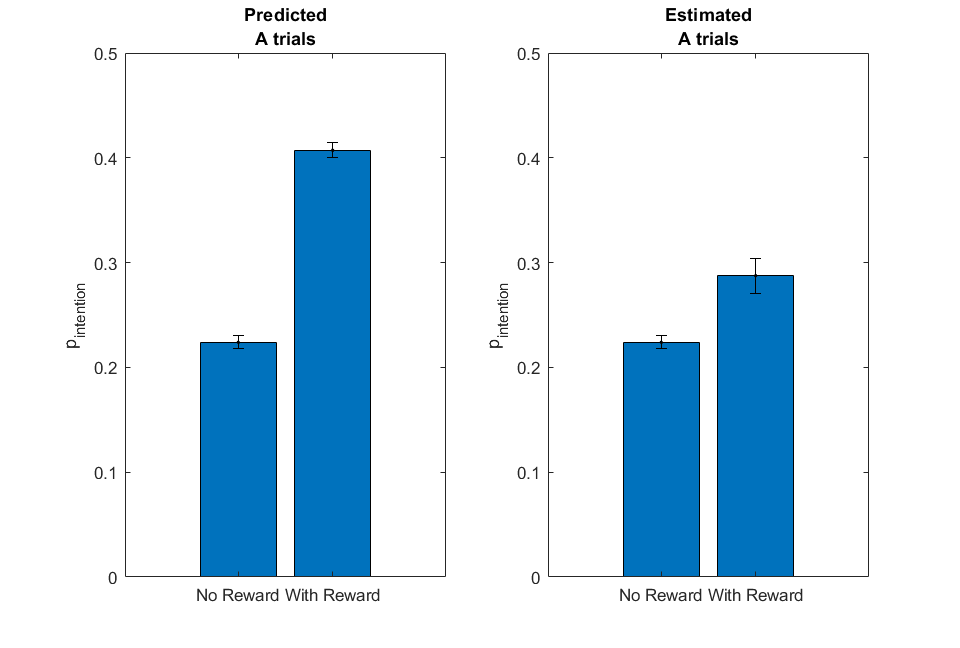

        hBar = bar(x1,y1);
        err1 = [SEM1,SEM3];
        hold on
        hEB=errorbar(x1,y1,err1,'k.');
        ylim([0,.5])
        yticks([0 .1 .2 .3 .4 .5])
        ylabel('p_{intention}','FontSize',16)
        title({'Estimated','A trials'},'FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)


% t test
        [mean(fitted_p_intentions(reward==0,1)), mean(fitted_p_intentions(reward==1,1))]

ans =     0.2239    0.2875


        [std(fitted_p_intentions(reward==0,1)), std(fitted_p_intentions(reward==1,1))]

ans =     0.0691    0.1947


        [h,p,ci,stats] = ttest2(fitted_p_intentions(reward==0,1),fitted_p_intentions(reward==1,1))

h = 1

p = 4.9132e-04

ci =    -0.0991
   -0.0281


stats = struct with fields:
    tstat: -3.5293
       df: 264
       sd: 0.1469


## Predicted probabilities across conditions

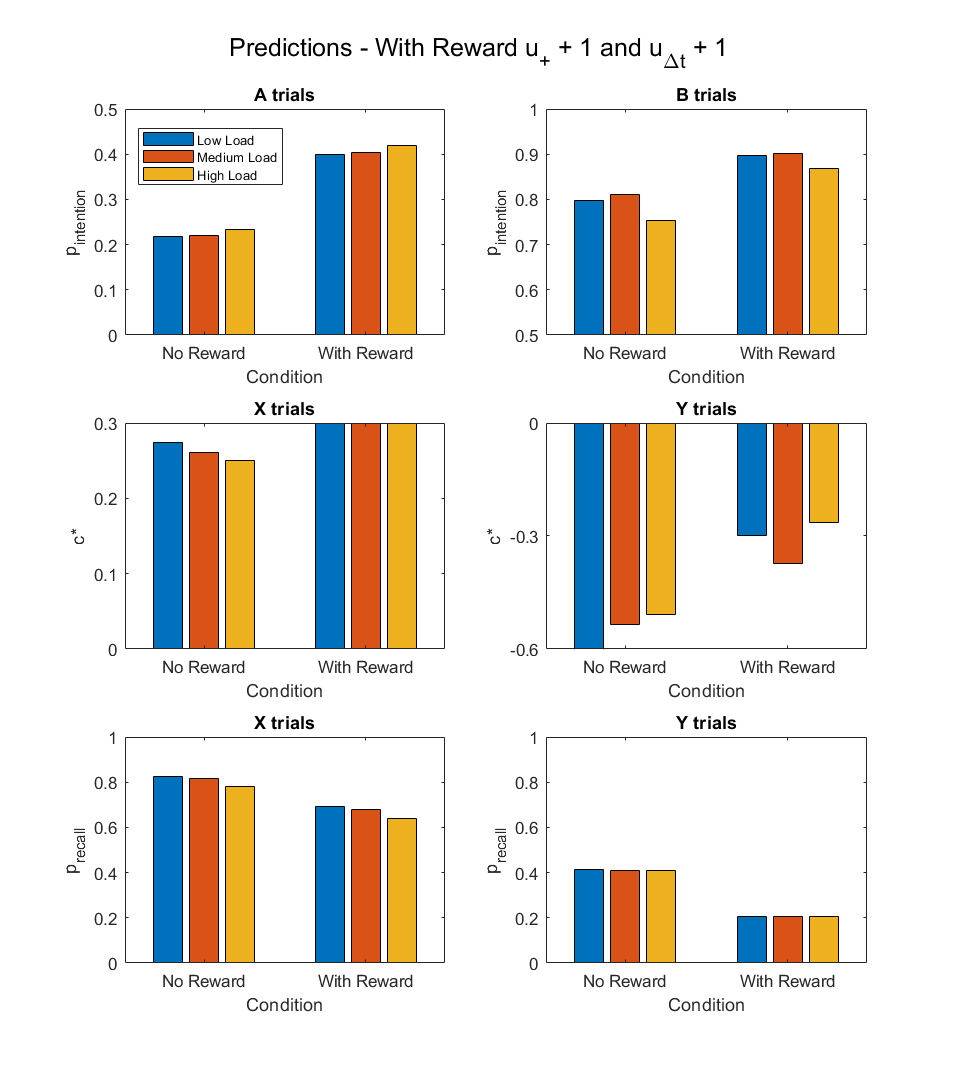

% p(intention) A trials
        figure('units','normalized','outerposition',[0.01 0.005 0.5 1], 'name','title')
        sgtitle({'Predictions - With Reward u_+ + 1 and u_{\Delta{}t} + 1'})
        subplot(3,2,1),
        bar([squeeze(fitted_p_intentions_cond([1],1,:)),pred_p_intentions2([1],:)']') % across load conditions - No reward
        ylim([0,.5])
        xlabel('Condition','FontSize',10)
        ylabel('p_{intention}','FontSize',16)
        title('A trials','FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)
        legend('Low Load','Medium Load','High Load','FontSize',8,'Position', [0.17 0.85 0.1 0.01])
        subplot(3,2,2),
        bar([squeeze(fitted_p_intentions_cond([3],1,:)), squeeze(pred_p_intentions2([3],:)')]') % across load conditions - with reward
        ylim([0.5,1])
        xlabel('Condition','FontSize',10)
        ylabel('p_{intention}','FontSize',16)
        title('B trials','FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)
% optimal_c 
        subplot(3,2,3),
        bar([squeeze(fitted_optimal_cs_cond([1],1,:)),pred_optimal_cs2([1],:)']') % across load conditions - No reward
        ylim([0,0.3])
        yticks([-.7 -.6 -.3 0 .1 .2 .3])
        ylabel('c*','FontSize',16)
        xlabel('Condition','FontSize',10)
        title('X trials','FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)
        subplot(3,2,4),
        bar([squeeze(fitted_optimal_cs_cond([2],1,:)),pred_optimal_cs2([2],:)']') % across load conditions - No reward
        ylim([-0.6,0])
        yticks([-.7 -.6 -.3 0 .1 .2 .3])
        ylabel('c*','FontSize',16)
        xlabel('Condition','FontSize',10)
        title('Y trials','FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)
% p_recall
        subplot(3,2,5),
        bar([squeeze(fitted_p_recalls_cond([1],1,:)),pred_p_recalls2([1],:)']') % across load conditions - No reward
        ylim([0,1])
        xlabel('Condition','FontSize',10)
        ylabel('p_{recall}','FontSize',16)
        title('X trials','FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)
        subplot(3,2,6),
        bar([squeeze(fitted_p_recalls_cond([2],1,:)),pred_p_recalls2([2],:)']') % across load conditions - No reward
        ylim([0,1])
        xlabel('Condition','FontSize',10)
        ylabel('p_{recall}','FontSize',16)
        title('Y trials','FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)

## Predicted Proactivity - error bars agreggate

        M1 = mean(GD_fitted(reward==0,1));
        M2 = mean(GD_pred);
        M3 = mean(GD_by_participant(reward==0))

M3 = 0.3982

        M4 = mean(GD_by_participant(reward==1))

M4 = 0.4641


        SEM1 = std(GD_fitted(reward==0,1))./sqrt(size(GD_fitted(reward==0,1),1));
        SEM2 = std(GD_pred)./sqrt(size(GD_pred,2));
        SEM3 = std(GD_by_participant(reward==0))./sqrt(size(GD_by_participant(reward==0),2));
        SEM4 = std(GD_by_participant(reward==1))./sqrt(size(GD_by_participant(reward==1),2));


        figure('units','normalized','outerposition',[0.1 0.005 0.5 0.6])
        subplot(1,2,1),
        y1 = [M1,M2];
        x1 = [1 2]

x1 =      1     2


        hBar = bar(x1,y1);
        err1 = [SEM1,SEM2];
        hold on
        hEB=errorbar(x1,y1,err1,'k.');
        ylim([0,.5])
        yticks([0 .1 .2 .3 .4 .5])
        ylabel('Proactivity (KL)','FontSize',16)
        %xlabel('Condition','FontSize',8)
        title({'Predicted'},'FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)
        subplot(1,2,2),
        y1 = [M3,M4]';
        x1 = [1 2]

x1 =      1     2


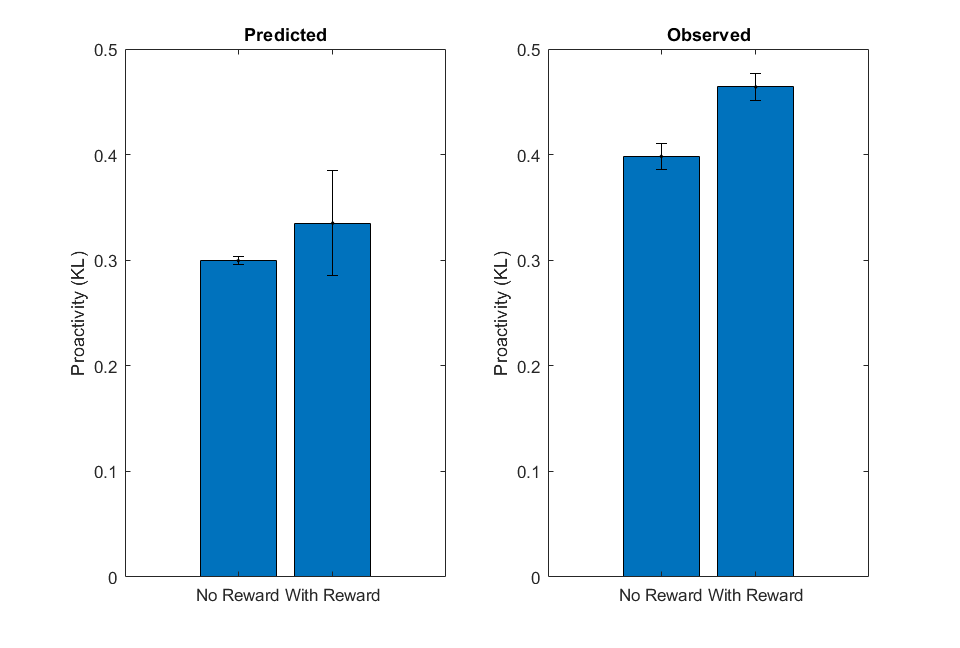

        hBar = bar(x1,y1);
        err1 = [SEM4,SEM4];
        hold on
        hEB=errorbar(x1,y1,err1,'k.');
        ylim([0,.5])
        yticks([0 .1 .2 .3 .4 .5])
        ylabel('Proactivity (KL)','FontSize',16)
        title({'Observed'},'FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)



% differences predicted
        [mean(GD_fitted(reward==0)), mean(GD_pred)]

ans =     0.2996    0.3351


        [std(GD_fitted(reward==0)), std(GD_pred)]

ans =     0.0429    0.0493


        [h,p,ci,stats] = ttest2(GD_fitted(reward==0), GD_pred)

h = 1

p = 1.9367e-09

ci =    -0.0468
   -0.0243


stats = struct with fields:
    tstat: -6.2235
       df: 260
       sd: 0.0462


## graph parameters by trial type - fitted

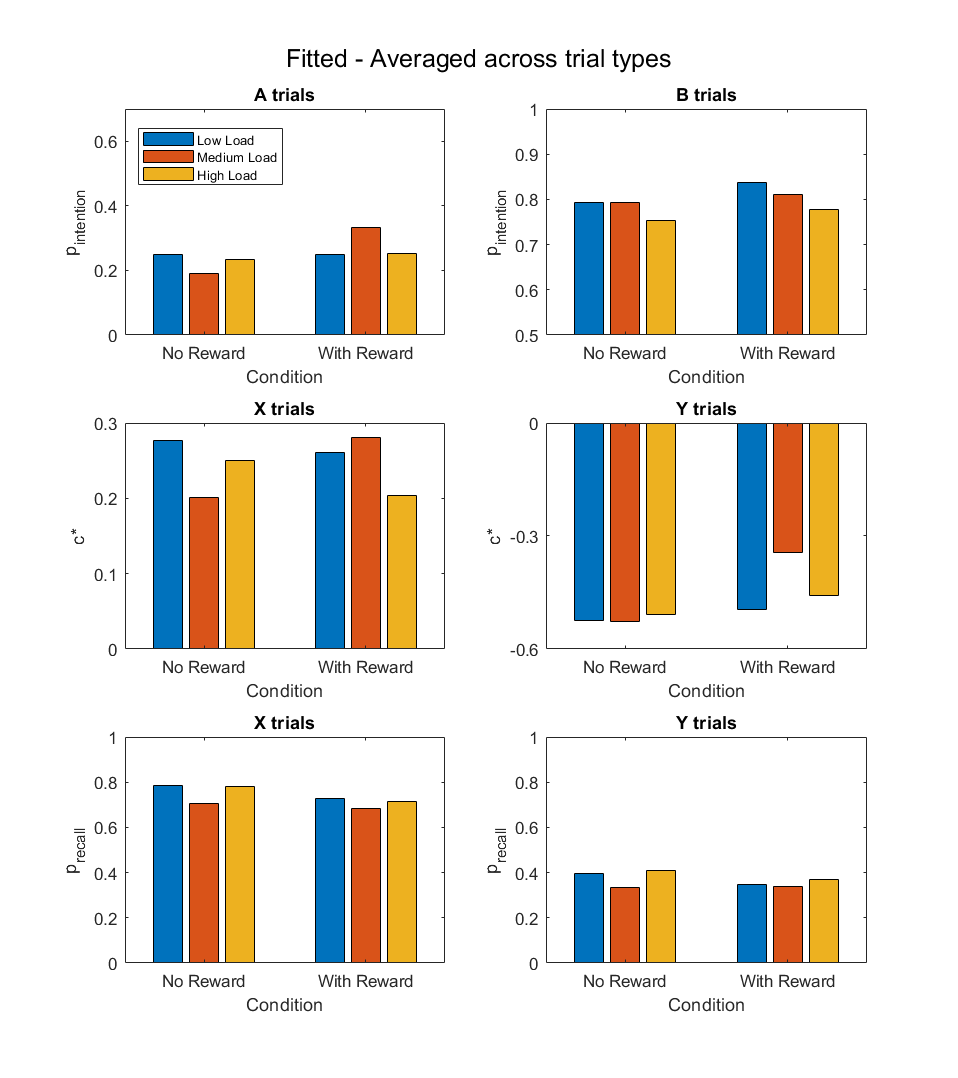

% p(intention)
        figure('units','normalized','outerposition',[0.1 0.005 0.5 1])
        sgtitle({'Fitted - Averaged across trial types'})
        subplot(3,2,1),
        bar([squeeze(fitted_p_intentions_cond([1],1,:)),squeeze(fitted_p_intentions_cond([1],2,:))]') % across load conditions - No reward
        ylim([0,.7])
        ylabel('p_{intention}','FontSize',16)
        xlabel('Condition','FontSize',8)
        title('A trials','FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)
        legend('Low Load','Medium Load','High Load','FontSize',8,'Position', [0.17 0.85 0.1 0.01])
        subplot(3,2,2),
        bar([squeeze(fitted_p_intentions_cond([3],1,:)),squeeze(fitted_p_intentions_cond([3],2,:))]') % across load conditions - No reward
        ylim([0.5,1])
        xlabel('Condition','FontSize',10)
        ylabel('p_{intention}','FontSize',16)
        title('B trials','FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)
% optimal_c
        subplot(3,2,3),
        bar([squeeze(fitted_optimal_cs_cond([1],1,:)),squeeze(fitted_optimal_cs_cond([1],2,:))]') % across load conditions - No reward
        ylim([0,0.3])
        yticks([-.7 -.6 -.3 0 .1 .2 .3])
        ylabel('c*','FontSize',16)
        xlabel('Condition','FontSize',10)
        title('X trials','FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)
        subplot(3,2,4),
        bar([squeeze(fitted_optimal_cs_cond([2],1,:)),squeeze(fitted_optimal_cs_cond([2],2,:))]') % across load conditions - No reward
        ylim([-0.6,0])
        yticks([-.7 -.6 -.3 0 .1 .2 .3])
        ylabel('c*','FontSize',16)
        xlabel('Condition','FontSize',10)
        title('Y trials','FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)
% p_recall
        subplot(3,2,5),
        bar([squeeze(fitted_p_recalls_cond([1],1,:)),squeeze(fitted_p_recalls_cond([1],2,:))]') % across load conditions - No reward
        ylim([0,1])
        xlabel('Condition','FontSize',10)
        ylabel('p_{recall}','FontSize',16)
        title('X trials','FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)
        subplot(3,2,6),
        bar([squeeze(fitted_p_recalls_cond([2],1,:)),squeeze(fitted_p_recalls_cond([2],2,:))]') % across load conditions - No reward
        ylim([0,1])
        xlabel('Condition','FontSize',10)
        ylabel('p_{recall}','FontSize',16)
        title('Y trials','FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)

## Model predictions for different loads

Predicting accuracy for load = 1, 2, 3 (no reward condition only). Fit to load 2, change load to 1 or 3. lambda min to 0.025.

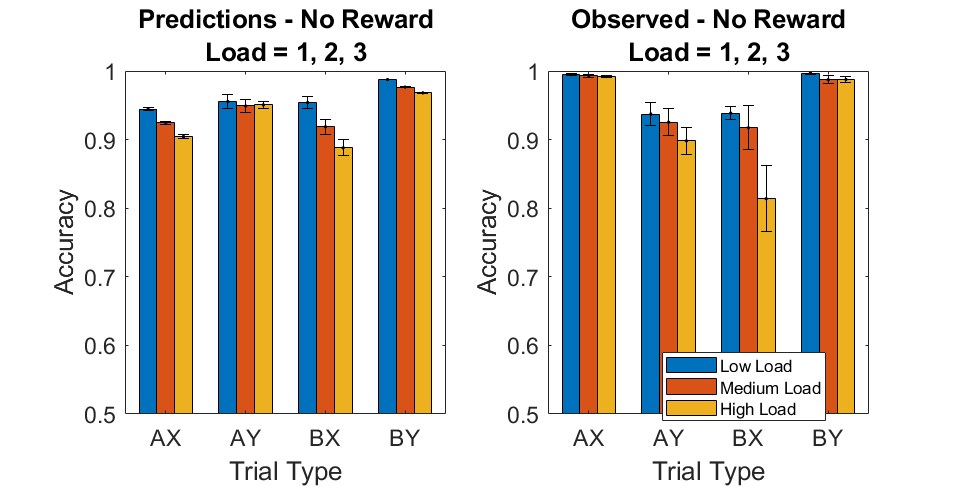

% Fitting model with lambda at least 0.025
        lambda_min = 0.025;
        
for s=1:nr_subjects
    [pars(s,:), fitted_accs(s,:), ll(s), fitted_p_intentions(s,:), fitted_optimal_cs(s,:), fitted_p_recalls(s,:), bic(s,:)]= ...
        fitMetaControlModel(modelName, isNoGo, accuracies(s,:), cognitive_load(s), trials,m,p_random_inhibition, p_cue_probe, p_slip, lambda_min);
end

clear acc_pred acc_pred_error pred_w_reactive pred_w_proactive pred_p_intentions pred_optimal_cs pred_p_recalls;
        alphas_p = [pars(reward==0 & cognitive_load==2,1)'];
        alphasAX_p = [pars(reward==0 & cognitive_load==2,2)']; 
        delta_ts_p = [pars(reward==0 & cognitive_load==2,4)']; 
        control_cost_p = [pars(reward==0 & cognitive_load==2,3)']; 
        interference_p = [pars(reward==0 & cognitive_load==2,5)']; 
        %interference_p = [repmat(0.025,1,42)];
        load_p = [1 2 3];
        load_p2 = [repmat(1,1,42), repmat(2,1,42), repmat(3,1,42)];
        

for l=1:size(load_p,2)     
    for n=1:size(accuracies(reward==0 & cognitive_load==2,1))
        [acc_pred(n,:,l), pred_p_intentions(n,:,l), pred_optimal_cs(n,:,l), pred_p_recalls(n,:,l)] = ...
          model(alphas_p(n),alphasAX_p(n),gamma,load_p(l),control_cost_p(n),delta_ts_p(n),interference_p(n),m,p_random_inhibition,p_cue_probe,p_slip);
    end
end



acc_pred_long = [acc_pred(:,:,1); acc_pred(:,:,2); acc_pred(:,:,3)];

    for l=1:3
        in_condition = cognitive_load==l;
        in_condition_pred = load_p2==l;
        accuracy_people(:,l) = mean(fitted_accs(in_condition,:));
        fitted_p_intentions_cond(:,l) = mean(fitted_p_intentions(in_condition,:));
        fitted_optimal_cs_cond(:,l) = mean(fitted_optimal_cs(in_condition,:));
        fitted_p_recalls_cond(:,l) = mean(fitted_p_recalls(in_condition,:));
        acc_pred_mean(:,l) = mean(acc_pred_long(in_condition_pred,:));
        acc_pred_error(:,l) = std(acc_pred_long(in_condition_pred,:))./sqrt(size(acc_pred_long(in_condition_pred,:),1));
        acc_obs_error(:,l) = std(accuracies(in_condition,:))./sqrt(size(accuracies(in_condition,:),1));
        fitted_p_intentions_cond_error(:,l) = std(fitted_p_intentions(in_condition,:))./sqrt(size(fitted_p_intentions(in_condition,:),1));
        GD_fitted_cond(:,l) = mean(GD_fitted(in_condition,:));
        GD_fitted_cond_error(:,l) = std(GD_fitted(in_condition,:))./sqrt(size(GD_fitted(in_condition,:),1));
    end

for l=1:3
    acc_ind_reward(:,l) = mean(acc_pred(load_p==l, :)); 
    pred_acc_error_reward(:,l) = std(acc_pred(load_p==l,:))./sqrt(size(acc_pred(load_p==l,:),1));
    pred_p_intentions2(:,l) = mean(pred_p_intentions(load_p==l,:));
    pred_optimal_cs2(:,l) = mean(pred_optimal_cs(load_p==l,:));
    pred_p_recalls2(:,l) = mean(pred_p_recalls(load_p==l,:));
    pred_p_intentions2_error(:,l) = std(pred_p_intentions(load_p==l,:))./sqrt(size(pred_p_intentions(load_p==l,:),1));
    GD_pred2(:,l) = mean(GD_pred(load_p==l,:))';
    GD_pred2_error(:,l) = std(GD_pred(load_p==l,:))./sqrt(size(GD_pred(load_p==l,:),1))';
end



% Predicted and Observed accuracies for different loads
        figure('units','normalized','outerposition',[0.1 0.1 0.5 0.45])
        subplot(1,2,1),
        %bar([squeeze(accuracy_people(:,1,:))]) % across cognitive load conditions - no reward
        y1 = squeeze(acc_pred_mean);
        hBar = bar(y1,1);
        err1 = squeeze(acc_pred_error);
        xBar=cell2mat(get(hBar,'XData')).' + [hBar.XOffset];  % compute bar centers
        hold on
        hEB=errorbar(xBar,y1,err1,'k.');
        ylim([0.5,1])
        ylabel('Accuracy','FontSize',16)
        xlabel('Trial Type','FontSize',16)
        title({'Predictions - No Reward','Load = 1, 2, 3'})
        %title({'Model Predictions - No Reward',['\alpha=', num2str(alphas(1), '%.2f'),'; u_{\Delta{}t}=', num2str(delta_ts(1),'%.2f'),';'], ['\lambda=', num2str(interference(1), '%.2f'), '; \delta=', num2str(control_cost(1),'%.2f')]},'FontSize',16)
        %legend('Low Load','Medium Load','High Load','FontSize',10)
        set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)

        subplot(1,2,2),
        y1 = [accuracies_no_reward'];
        hBar = bar(y1,1);
        err1 = squeeze(acc_obs_error(:,1,:));
        xBar=cell2mat(get(hBar,'XData')).' + [hBar.XOffset]; 
        hold on
        hEB=errorbar(xBar,y1,err1,'k.'); % across cognitive load conditions - no reward
        %bar([squeeze(predicted_accuracy(:,1,1)), accuracies_cond(1,:)'])
        ylim([0.5,1])
        ylabel('Accuracy','FontSize',16)
        xlabel('Trial Type','FontSize',16)
        title({'Observed - No Reward','Load = 1, 2, 3'}, 'FontSize',16)
        legend('Low Load','Medium Load','High Load','FontSize',10, 'Position', [0.77 0.2 0.01 0.01])
        set(gca,'XTickLabel',experiment.trial_types,'FontSize',14)

## Correlation between predicted and observed Goal Directedness and Reactivity measures

%% Predicted Proactivity - error bars agreggate
        M1 = mean(GD_fitted(reward==0,1));
        M2 = mean(GD_pred);
        M3 = mean(GD_by_participant(reward==0))

M3 = 0.3982

        M4 = mean(GD_by_participant(reward==1))

M4 = 0.4641


        SEM1 = std(GD_fitted(reward==0,1))./sqrt(size(GD_fitted(reward==0,1),1));
        SEM2 = std(GD_pred)./sqrt(size(GD_pred,2));
        SEM3 = std(GD_by_participant(reward==0))./sqrt(size(GD_by_participant(reward==0),2));
        SEM4 = std(GD_by_participant(reward==1))./sqrt(size(GD_by_participant(reward==1),2));


        figure('units','normalized','outerposition',[0.1 0.005 0.5 0.6])
        subplot(1,2,1),
        y1 = [M1,M2];
        x1 = [1 2]

x1 =      1     2


        hBar = bar(x1,y1);
        err1 = [SEM1,SEM2];
        hold on
        hEB=errorbar(x1,y1,err1,'k.');
        ylim([0,.5])
        yticks([0 .1 .2 .3 .4 .5])
        ylabel('Goal Directedness (KL)','FontSize',16)
        %xlabel('Condition','FontSize',8)
        title({'Predicted'},'FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)
        subplot(1,2,2),
        y1 = [M3,M4]';
        x1 = [1 2]

x1 =      1     2


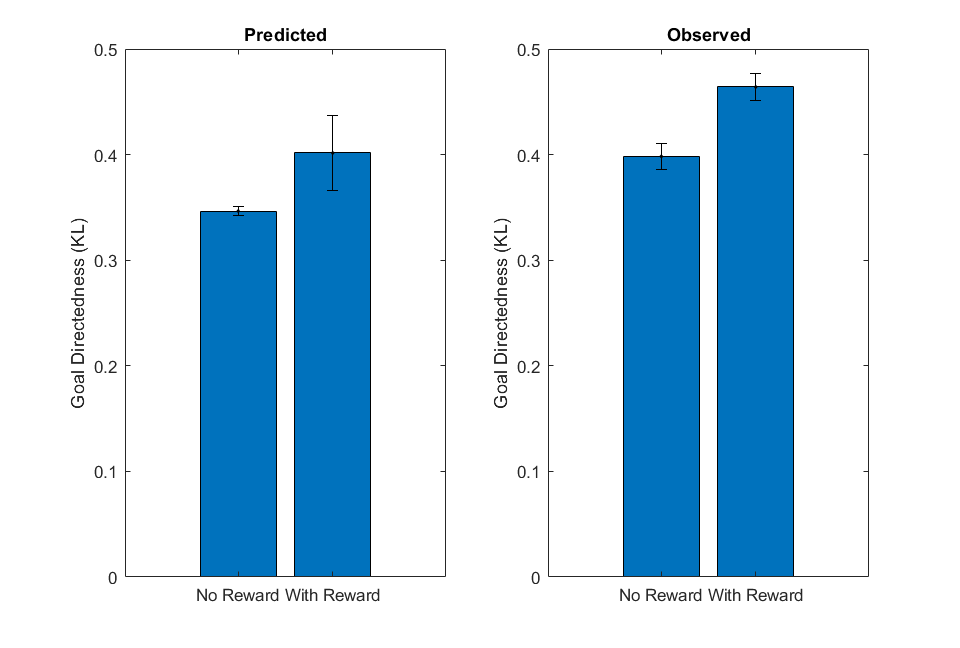

        hBar = bar(x1,y1);
        err1 = [SEM4,SEM4];
        hold on
        hEB=errorbar(x1,y1,err1,'k.');
        ylim([0,.5])
        yticks([0 .1 .2 .3 .4 .5])
        ylabel('Goal Directedness (KL)','FontSize',16)
        title({'Observed'},'FontSize',16)
        set(gca,'XTickLabel',{'No Reward','With Reward'},'FontSize',10)



% cor predicted and observed
        [mean(GD_fitted(reward==0)), mean(GD_pred)]

ans =     0.3465    0.4016


        [std(GD_fitted(reward==0)), std(GD_pred)]

ans =     0.0486    0.0353


        [h,p,ci,stats] = ttest2(GD_fitted(reward==0), GD_pred)

h = 1

p = 1.0363e-21

ci =    -0.0654
   -0.0448


stats = struct with fields:
    tstat: -10.4938
       df: 260
       sd: 0.0425
